# 4. Fourier Integral (Fourier Transform)

## 4.1 Basics

## 4.3 Some examples 

## 4.4 Some properties

## 4.7 Convolution

## 4.10 Hilbert transform

####    - Example 4.2: envelope

####    - Example 4.3: Hilvert transform

####    - Example by CJH

## 4.11 Effect of data truncation

####    - Example 4.6: time window length and practice smearing

####    - Homework #1

## 4.1 Basics

Fourier integral is the limit of Fourier series as follows.

- integral over finite period is extended to the -inf to +inf.

- discrete frequency cn, n=1, . . . is turned into continuous frequency f.

As a result, the periodicity is disappeared. 

Let's begin with

The Fourier transformation of x(t) becomes

Since X is complex, we may write

Same as discrete version, in which amplitude cn =sqrt(an2+bn2)/2, phase  $\phi n=\ {tan}^{-1}$ n =  (bn/an). One is amplitude, the other the phase angle. |X(f)| is even,  (f) is odd. 

We can plot each of these in the figure. Also, another plot is available, which draws Re and Im in one graph.

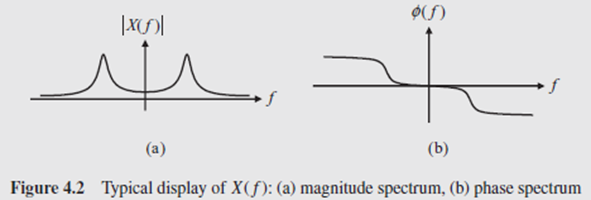  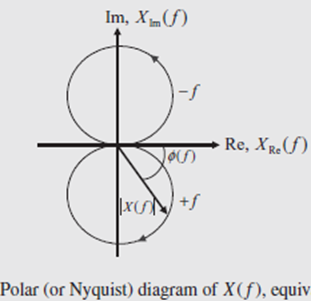

cn^2 is the power in Fourier series. X(f)^2 is energy spectral density in Fourier transform.

Therefore, power spectrum is interchangeably used with energy spectrum.

   

## 4.3 Some examples 

Delta function 

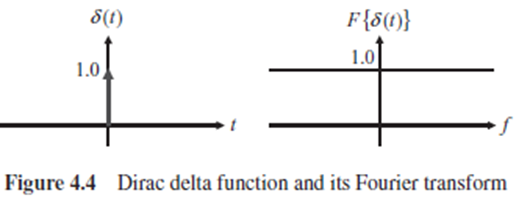

Exponentially decaying symmetric function (phase is zero.)

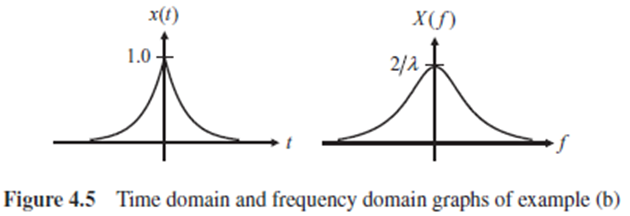

Exponentially decaying function (amplitude is half the symmetric case.)

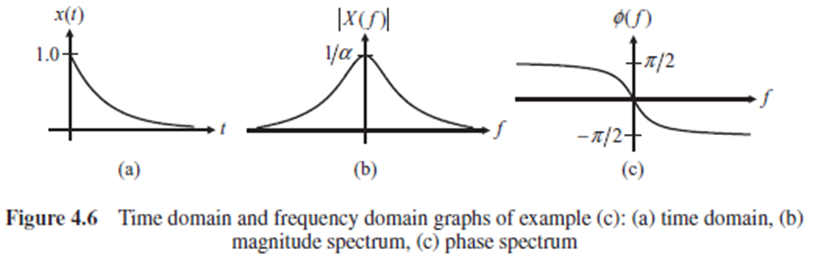

Sine function  

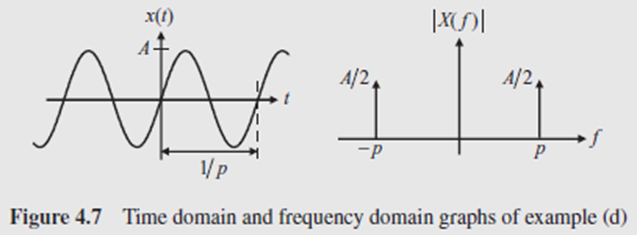

Rectangular pulse

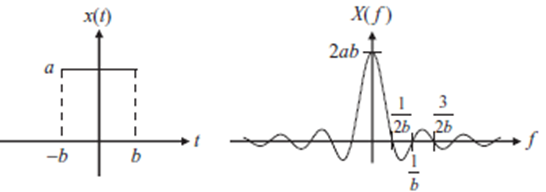

Damped symmetrically oscillating function

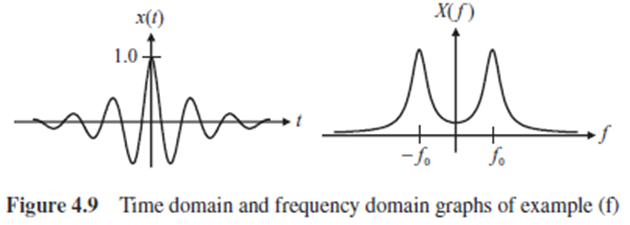

Damped oscillating function only positive side

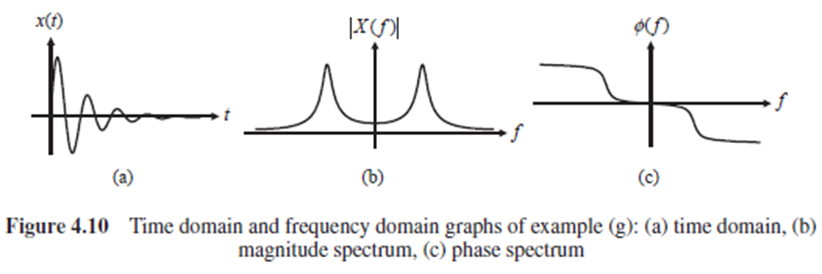

## 4.4 Some properties

a) Time scaling: 

c) Time shifting:  

e) Differentiation:

f) Convolution:    where 

g) Another convolution:  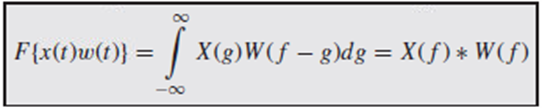

1. A symmetrical signal has a real-valued transform, i.e. its phase is zero. 

2. A pure delay imposed on a signal results in a linear phase change to the transform

(see property (c) in Section 4.4). An example of this is illustrated in Figure 4.13.

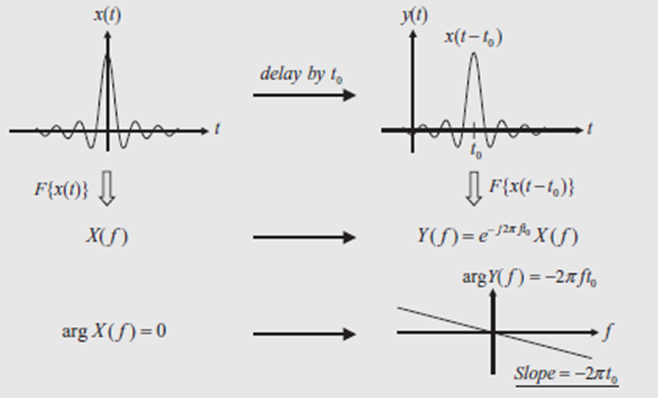

## 4.7 Convolution

Consider a linear time-invariant system.

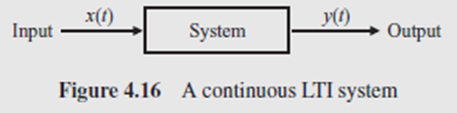

Linearity and time invariance are

Typical example of the system is

We define the response of the system for a unit impulse at t = 0 to be h(t). we say that the system is causal, i.e., h(t)=0 when t<0. In other words, y(t) at t=t1 is dependent only on the past of x(t) with t<t1, not the future of x(t), which is the case in reality.

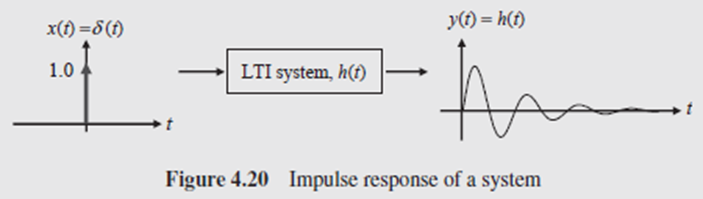

For a signal  $x{\left(t_1 \right)}\Delta t_1$  at $t_1$ , the subsequent response becomes $h{\left(t-t_1 \right)}x{\left(t_1 \right)}\Delta t_1$ where $t\ge t_1$ .

Adding all the responses to such impulses, the total response at time t (the present) becomes

where  $t_1 \le t$ is time at which the input impulse has occurred. If we substitute $t-t_1 =\tau$ , then

If the input x(t) is zero for t<0, which is the case in reality

If further the system is non-causal, i.e., the system y(t) at current t also responds to future inputs of x(t1), t1>t, the equation becomes

Or simply 

The meaning of integral over reverse direction is illustrated as follows.

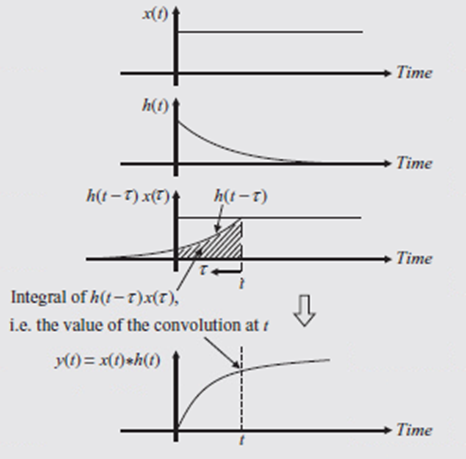

When x(t), h(t) are given as left figures, its convolution is the integral of h(t-t)x(t), where t goes reverse direction up to the zero point at current time t. As a result, at a time t, its value is the area in the third figure which is the height with dash line in fourth figure.

As time t goes to the right, the area increases but soon converges to constant because h(t) becomes zero as second figure shows.

## 4.10 Hilbert transform

**Hilbert transform** $\hat{x} {\left(t\right)}$ is the convolution of $x{\left(t\right)}$ with $h{\left(t\right)}=1/\pi t$  

Then the FT of this becomes

 where  

In this sense, Hilbert transform is often referred to as a 90◦ phase shifter, i.e., the phase of original signal x(t) is shifted by 90◦ in   . For example, Hilbert transform of x(t) = cos ω0t is   = sin ω0t. 

Check whether  $\hat{X} {\left(f\right)}=X{\left(f\right)}\cdot {\left(-jsgn{\left(f\right)}\right)}$ in this example.

For any real valued signal x(t), if we make HT signal  , then it is the phase shifted signal by 90 degree.

 

Ax(t) is instantaneous amplitude, and phi is instantaneous phase.

    

For example, x(t) = cos w0*t. the analytic signal becomes ax(t) = exp(j*w0*t) where Ax(t)=1, wx(t)=w0. Both are constants. In reality, these are functions in time.

**Consider amplitude-modulated signal:**

  

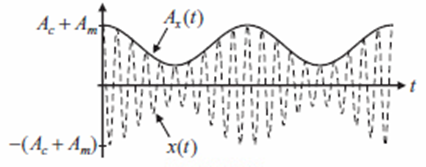

In this function, m(t) is the amplitude of signal. HT of x(t) is $\hat{x} {\left(t\right)}=m{\left(t\right)}sin\omega_c t$                       . 

Analytical signal is

where the instantaneous amplitude is Ax(t), also called envelope since it is the envelope of x. Also, the instantaneous phase is $\phi_x {\left(t\right)}=\omega_c t$ and its frequency (derivative of  $\phi$) is constant.

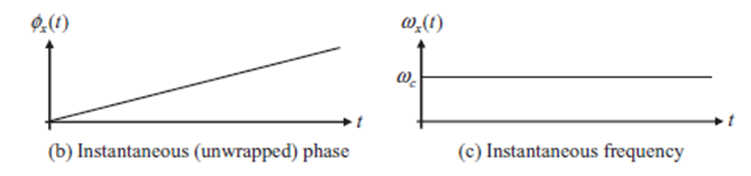

Envelope analysis is to extract this envelope Ax(t) from the original signal x(t). To do this, make the complex analytic signal ax(t) by adding the HT. Then evaluate the amplitude of this signal. This is used for the early detection of a machine fault. 

For example, a fault in an outer race of a rolling bearing may generate a series of burst signals at a regular interval. Such burst signals decay very quickly and contain relatively small energies, thus the usual Fourier analysis may not reveal the repetition frequency of the bursts. However, it may be possible to detect this frequency component by forming the analytic signal and then applying Fourier analysis to the envelope Ax (t).

**Consider frequency modulated signal:**

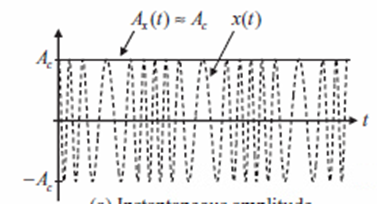

The amplitude of this signal is constant. Instead, the frequency fluctuates.

Analytic signal is 

The instantaneous amplitude is simple Ac. Instantaneous phase and its frequency are given as

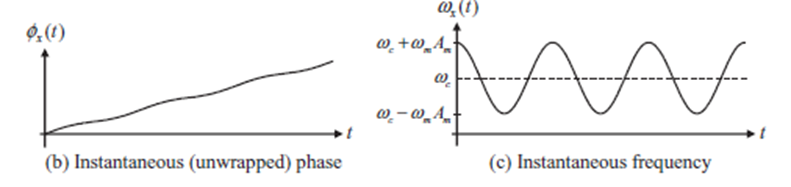

#### Example 4.2: envelope

In order to understand what is envelope, practice example 4.2.

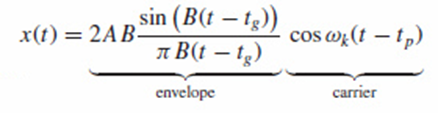

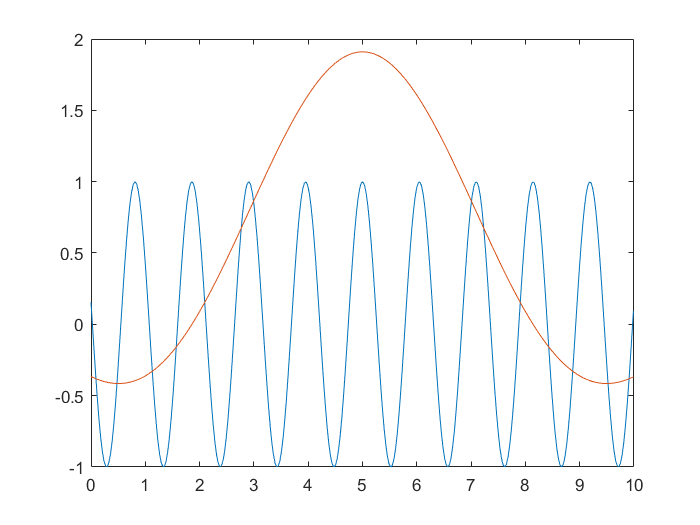

clear all; close all;
B=1; A=3; wk=6; tg=5; tp=5; t=0:0.03:10; 
x=2*A*B*sin(B*(t-tg))./(pi*B*(t-tg)).*cos(wk*(t-tp));
xe=2*A*B*sin(B*(t-tg))./(pi*B*(t-tg)); xc= cos(wk*(t-tp)); x=xe.*xc;
plot(t,xc,t,xe); % let's plot carrier and envelope respectively.`

figure(1); plot(t,x); xlabel('Time (s)'); ylabel('\itx\rm(\itt\rm)'); hold on; plot(t, xe, 'r:', t, -xe, 'r:'); hold off; grid on

Also, review the example 2.1 and the comments there, which has examined sine signal:                                $sin2\pi p_1 t+sin2\pi p_2 t$ where p1 p2 are 1.4 1.5 respectively. Note that the signal can be transformed to


$$sin2\pi p_1 t+sin2\pi p_2 t=2sin2\pi \frac{p_1 +p_2 }{2}tcos2\pi \frac{p_1 -p_2 }{2}t=2cos2\pi f_e t\cdot sin2\pi f_c t$$
 

which can be interpreted as the envelope with freq. fe = (1.5-1.4)/2=0.05 and carrier with freq. fc = (1.5+1.4)/2=1.45. FFT of this signal gives us the peak at two locations p1 = (fc+fe)=1.4, p2=(fc-fe)=1.5 which is the two shifts with distance fe centered at fc.

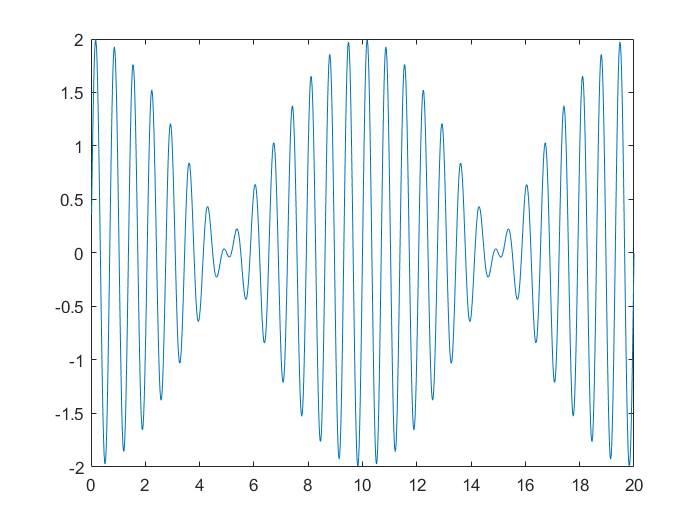

clear all; close all;
p1=1.4; p2=1.5; fe=(p2-p1)/2; fc=(p2+p1)/2; 
fs=50; T=20; t=1/fs:1/fs:T; 
x0=sin(2*pi*p1*t)+sin(2*pi*p2*t); 
x=2*cos(2*pi*0.05*t).*sin(2*pi*1.45*t);
figure(1); plot(t,x); % you will see x and x0 are identical.

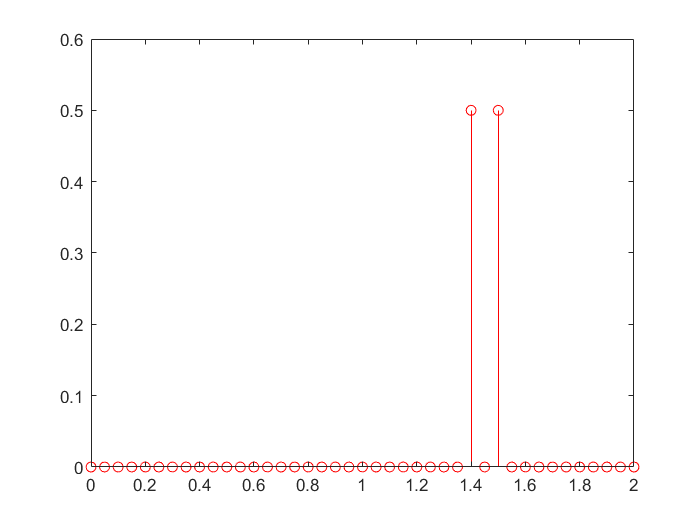

N=length(x); X=fft(x); f=fs*(0:N-1)/N; 
figure(2); stem(f(1:N/2+1), abs(X(1:N/2+1)/fs/T), 'r'); xlim([0 2])

#### Example 4.3: Hilvert transform

When signal x(t) includes envelope and carrier signal, HT is useful to extract the envelope. 

After HT, we will get analytical signal ax(t) which is the complex version of x(t).

Then abs(a(x)) is simply the envelope of the original signal x(t).

This is also called demodulation.

Note that the envelope freq. fm = 1, carrier freq. fc = 10.

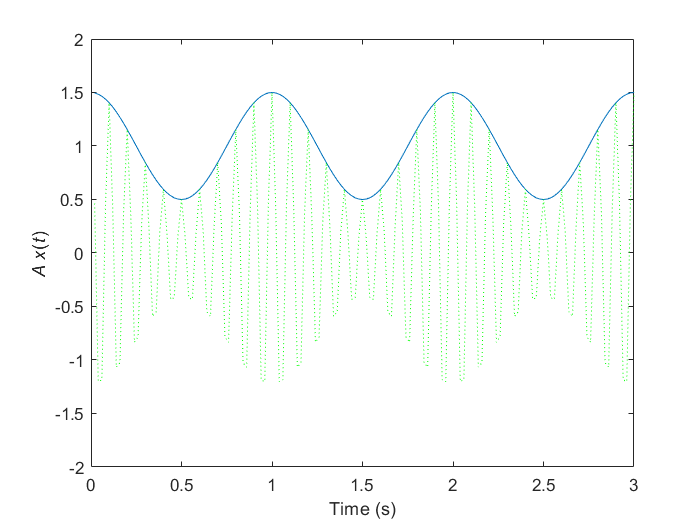

clear all; close all;
Ac=1; Am=0.5; fm=1; fc=10; % try different Am = 0.5 & 1.5.
fs=50; T=3; t=1/fs:1/fs:T;
x=(Ac+Am*cos(2*pi*fm*t)).*cos(2*pi*fc*t); 
a=hilbert(x); aa=abs(a);

figure(1); plot(t, aa, t, x, 'g:'); axis([0 3 -2 2])
xlabel('Time (s)'); ylabel('\itA x\rm(\itt\rm)')

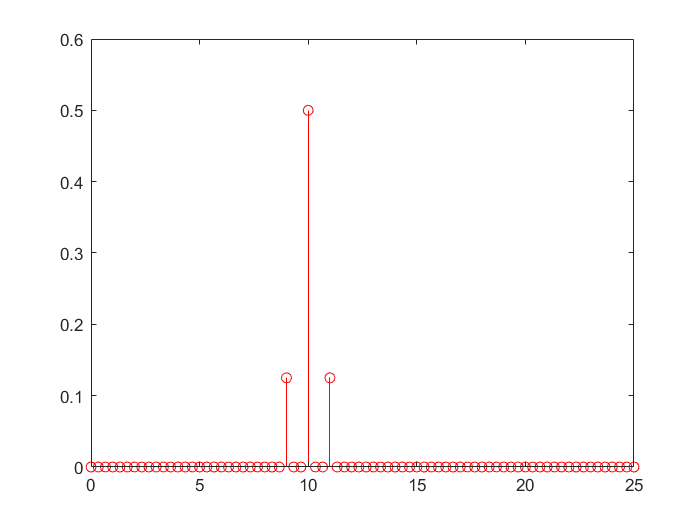


N=length(x); X=fft(x); f=fs*(0:N-1)/N; 
figure(2); stem(f(1:N/2+1), abs(X(1:N/2+1)/fs/T), 'r'); 

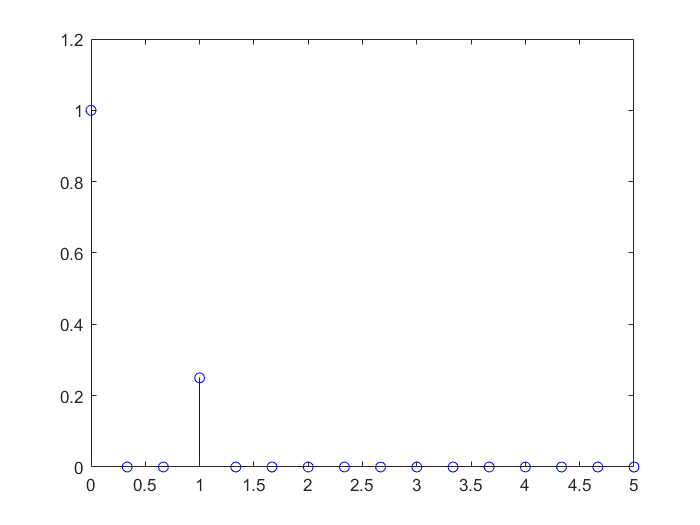


N=length(a); A=fft(aa); f=fs*(0:N-1)/N; 
figure(3); stem(f(1:N/2+1), abs(A(1:N/2+1)/fs/T), 'b'); xlim([0 5])

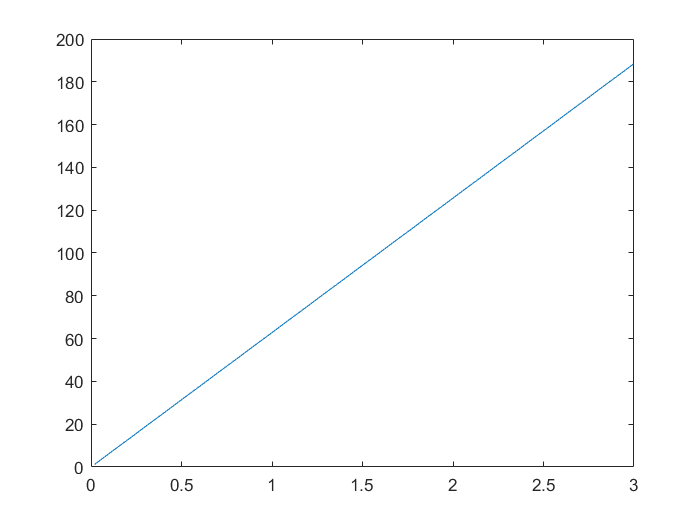


figure(4); plot(t, unwrap(angle(a))); axis([0 3 0 200])

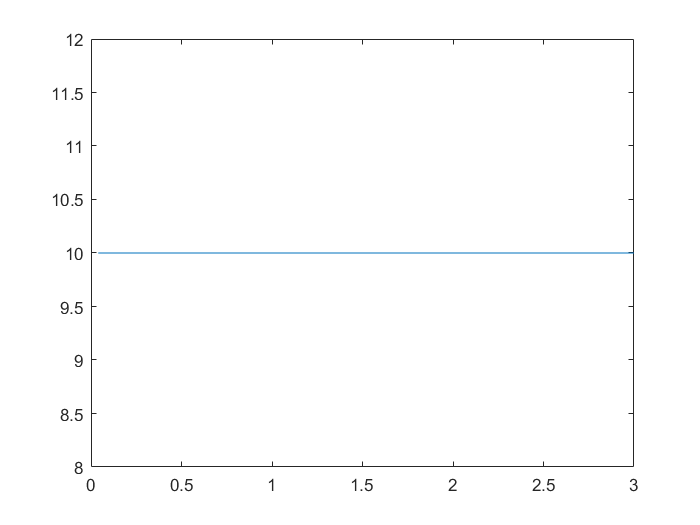

fx=diff(unwrap(angle(a)))./diff(t)/(2*pi);
figure(5); plot(t(2:end),fx); axis([0 3 8 12])

The original FFT did not capture the envelope signal, while the analytic signal by Hilbert transform does exactly at freq fm=1 with peak Am/2 = 0.25, which shows the importance of Hilbert transformation. Though not implemented here, frequency modulated signal is given in Example 4.5. only the result is given here.

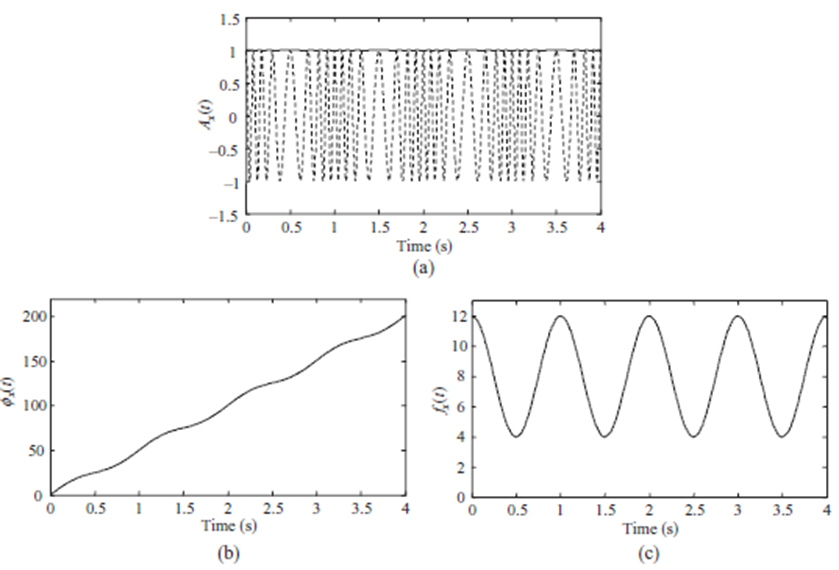

#### Example by CJH

Due to its importance, the concept of the envelope is explained via example once again. Since we can generate virtual modulated signal in this example, it is easier to understand the concept.

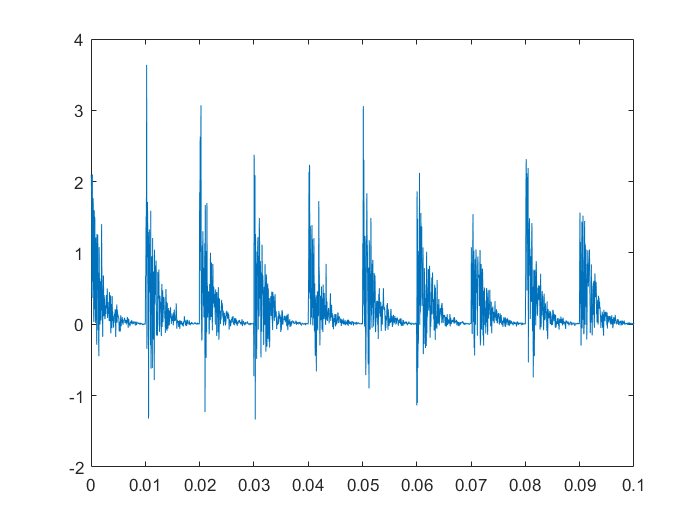

clear all; close all;
p=100; Tp=1/p; B=500; T=10*Tp; wk=5000; 
fs=20000; t=1/fs:1/fs:T; N=length(t);
for j=1:N; tj=t(j); for i=1:20; 
if tj>(i-1)*Tp & tj<=i*Tp; tt=tj-(i-1)*Tp; xe(j)= exp(-B*tt); 
end; end; end; xe=xe.*(1+randn(size(xe))); figure(1); plot(t,xe)

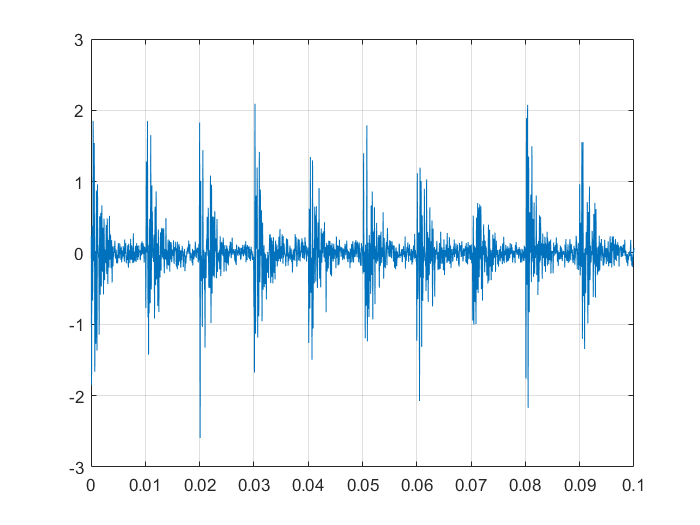

x=xe.*cos(2*pi*wk*t);
n=randn(size(x)); n=0.2*sqrt(2)*(std(x)/std(n))*n; x=x+n;
figure(2); plot(t,x); grid on; 

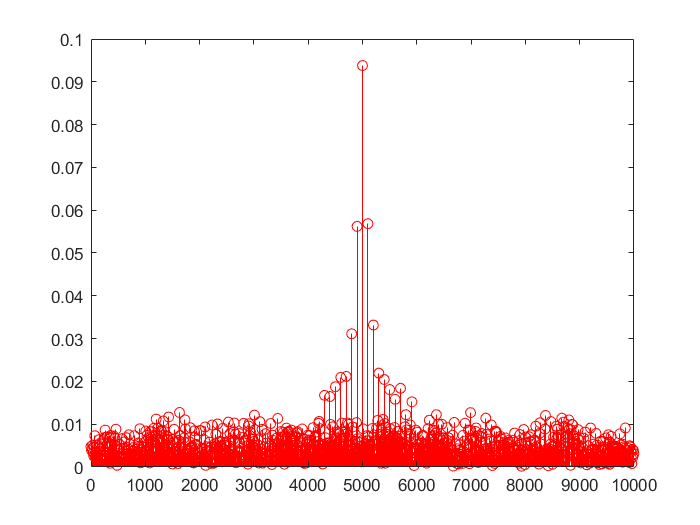


X=fft(x); f=fs*(0:N-1)/N; 
figure(3); stem(f(1:N/2+1), abs(X(1:N/2+1)/fs/T), 'r'); 

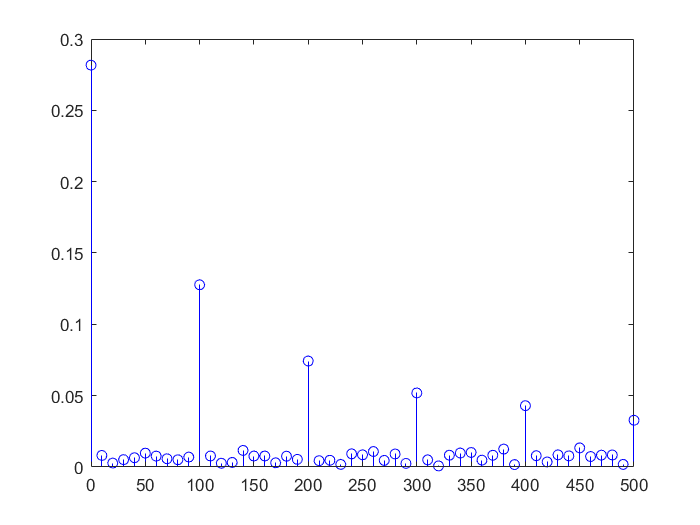


a=hilbert(x); aa=abs(a);
N=length(a); A=fft(aa); f=fs*(0:N-1)/N; 
figure(4); stem(f(1:N/2+1), abs(A(1:N/2+1)/fs/T), 'b'); xlim([0 500])

Raw signal includes envelope with exp(-Bt). Plain FFT gives us the 2nd figure, while the envelope includes 3rd where frequency range is reduced to [0 500].

## 4.11 Effect of data truncation

For an arbitrary signal with the data truncated for the period (-T/2 T/2) as follows,

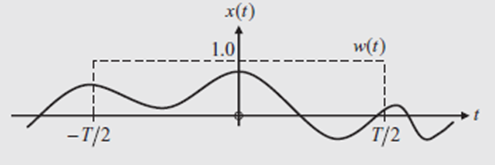

in fact, this is to make the original x(t) into xT(t) = x(t)w(t) where w is

Based on the theorem, we get

i.e. the Fourier transform of the product of two time signals is the convolution of their Fourier transforms.

If we have rectangular window w(t) like this, its FT is given as follows.

 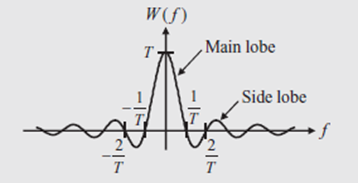

We have smearing and leakage of the original FT of x due to the window w(t).

Smearing is due to the main lobe shape. Leakage is due to the side lobe.

For example, consider a cosine curve x(t) = cos(2pi p t). original FT of this curve is 

After convolution operation with rectangular window, we get following solution instead of delta function

which means that the original delta function at p is turned into W(f) at p. Compare the two as follows.

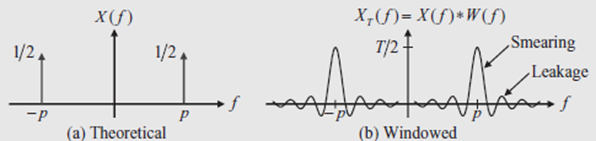

In practical FFT, however, we get the right side only. In FFT, the value is the discrete mass. In FT, the value is the continuous density. 

In case of closely spaced sine signal, it may not be easy to distinguish in the freq. domain due to the distortion. In this case, increase the time window sufficiently to have more resolution between frequencies as shown in the following figure.

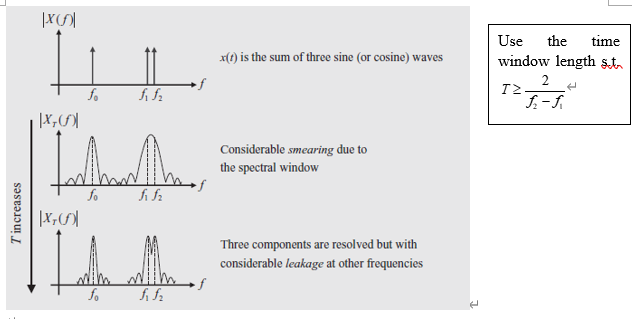

The curve is FT result. In FFT, only heights at discrete points are obtained. 

There are other types of windows, as an alternative of rectangular window to reduce the side lobes but the width of main lobe gets wider, i.e., smearing is increased. That is, other windows are introduced to reduce leakage at the expense of main lobe width in Fourier transform calculations, i.e. to obtain windows with small side lobes.

- 20% cosine tapered window

- Hann (Hanning) window (full cosine tapered window)

- Hamming window

- Etc.

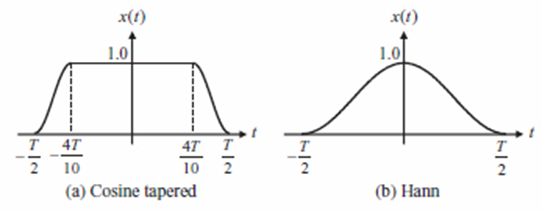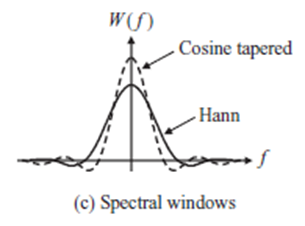

Read general comments on windows at pages 97-100 of the textbook.

#### Example 4.6: time window length and practice smearing

Sum of three sine waves with different frequencies

Note that the peiod of resulting signal is the least common multiple of 1/f1, 1/f2, 1/f3 where f’s are 10, 20 and 21.

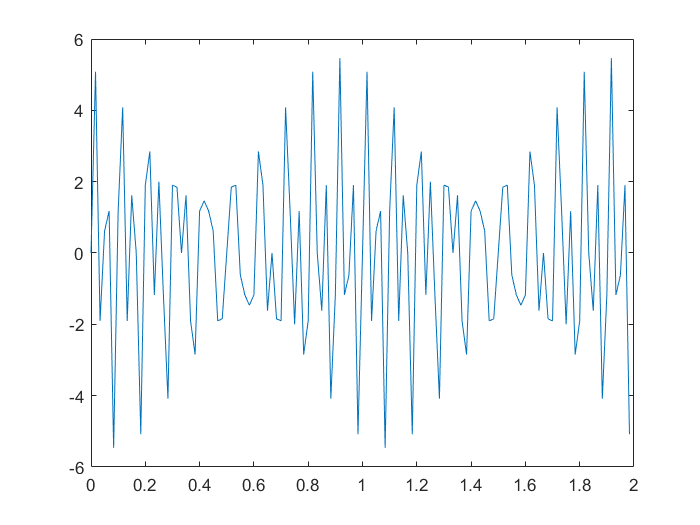

% try T = 0.6, 0.8, 1.0, 1.5, 2, 2.5, 3, 4.
% try fs = 60 & 1000.
clear all; close all
f1=10; f2=20; f3=21; fs=60; T=2; 
t=0:1/fs:T-1/fs; % T time window. fs sampling rate (Hz)
x=2*sin(2*pi*f1*t)+2*sin(2*pi*f2*t)+2*sin(2*pi*f3*t); 
figure(1); plot(t,x)

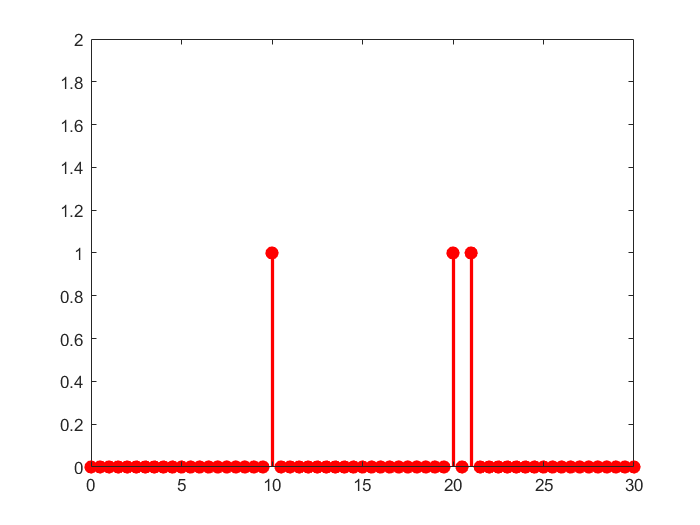

N=length(x); X=fft(x); f=fs*(0:N-1)/N; 
figure(2); stem(f(1:N/2+1), abs(X(1:N/2+1)/fs/T),'r','fill','LineWidth',2); axis([0 30 0 2])

Effect of time window in DFT

T=0.6 and fs=60, we get a symmetric form over the entire frequency range (0, 60) Hz, due to the aliasing effect that will be mentioned later. So plot only the left half.

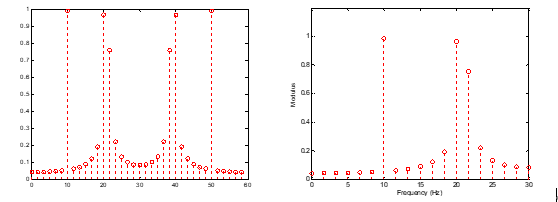

If we change T to various values 0.6, 1.0, 1.5, 2.0, 2.5, then we get

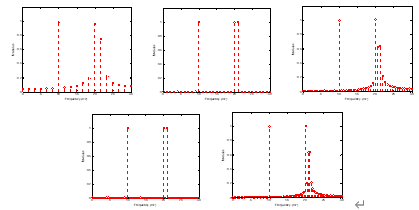

Remarks on the example

 - Sampling frequency fs: Freq. of each sine wave are 10, 20, 21. Increasing fs does not help the solution improvement because it just indicates max frequency value. fs such that includes frequencies 10, 20 & 21, hence, more than twice of this max is enough, because the information is only at the left half of the fs due to the aliasing effect.

- Time window T: Period of resulting wave is 1. The reason is that LCM of 1/420*(42,21,20) = 1/420*(420) = 1. So, when time window is exact or multiples of period T=1, we get exact answer. Otherwise, we lose some information due to time window with wrong period. If we don’t know this period, what we can do is to increase T as long as possible. The three frequency components are identified more clearly as T increases. The frequency resolution is also improved, i.e., denser along the frequency axis.

#### Homework #1

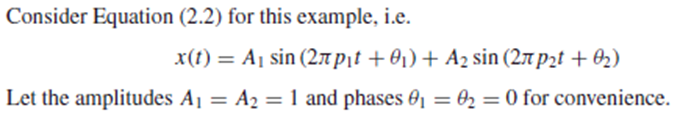

- Plot the signal in time domain and Fourier coefficients in the frequency domain when p1, p2 = 1.4, 1.5. what is the period of resulting signal and how do you calculate it ?

- Plot the signal in time domain and Fourier coefficients in the frequency domain when p1=Ö2, p2=1.5. what is the period of resulting signal ? 

Carry out the FFT using the MATLAB for each of the following conditions for the sampling rate fs and time window T. Plot the amplitudes for the left half of fs in the frequency domain and comment on the results for each case. 

When p1, p2 = 1.4, 1.5, 

- fs=5, T=10

- fs=50, T=10 (increased sampling rate)

- fs=5, T=100 (increased time window)

- fs=3, T=10 (reduced sampling rate with max at 1.5 Hz)

- fs=5, T=9 (inexact time window)

- fs=50, T=9 (inexact time window with increased fs)

When p1=sqrt(2), p2=1.5, 

- fs=5, T=10 (same condition as the (3) above)

- fs=50, T=10 (increased sampling rate)

- fs=5, T=100 (increased time window)

- fs=5, T=1000 (further increased time window)

Consider example 4.2 that includes envelope and carrier signals.

For this problem, apply

B=1; A=3; wk=6; tg=5; tp=5; t=0:0.03:10;


- Plot the ogirinal x(t) and its envelope in superposition.

- Do the HT to get the analytic signal and extract envelope signal. Then plot it and check whether it agrees with the envelope plotted in 1).

- Do the FFT of orginal signal x(t) and envelope signal respectively. Compare the results and comment on it.

 For the example 4.6, in which the signal consists of 3 sine waves

- Let T=1.0. For fs=30, 40, 50, do FFT and compare the results.

- Let fs=60, for T=.6, 1.0 1.5, 2.0 2.5, 3.0, 3.5, do FFT and compare the results.

#### [Next Chapter](matlab:open('./Ch_5')) >

#### [Return Overview](matlab:open('./PHM_Overview.mlx')) >